% Import table
step_Kp15 = readtable("step_Kp15.csv");

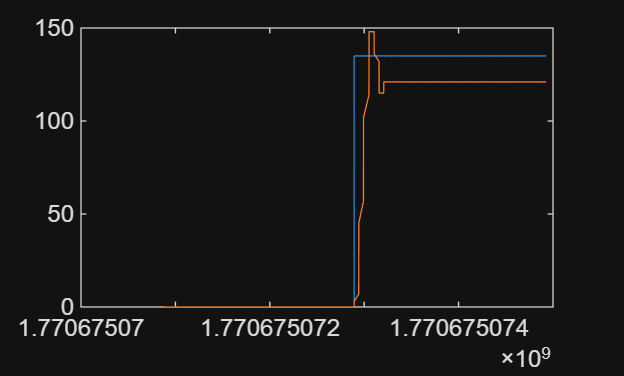

plot(step_Kp15.timestamp, step_Kp15.target, step_Kp15.timestamp, step_Kp15.current);

%% Extract and normalize time
t = step_Kp15.timestamp;
u = step_Kp15.target;
y = step_Kp15.current;

t = t - t(1);                         % start at 0
dt = diff(t);
Ts = median(dt);

% Check sampling jitter (optional but recommended)
jitter = std(dt);
fprintf('Ts = %.6g s, jitter std = %.6g s\n', Ts, jitter);

Ts = 0.000210524 s, jitter std = 0.0226851 s



%% Resample to a uniform time base (recommended)
tq = (0:Ts:t(end)).';                 % uniform time vector
u = interp1(t, u, tq, 'previous', 'extrap');   % ZOH for command
y = interp1(t, y, tq, 'linear',   'extrap');   % linear for measurement
t = tq;

%% Robust step start detection (handles noise)
du = [0; diff(u)];
thr = 0.2 * max(abs(du));             % threshold relative to biggest jump
k0  = find(abs(du) > thr, 1, 'first'); % step index

if isempty(k0)
    error('Could not detect a step change in u.');
end

pre  = 50;                             % samples before step to keep
post = length(t);                      % keep to end (or set a window)
i0 = max(k0 - pre, 1);
i1 = post;

t2 = t(i0:i1);
u2 = u(i0:i1);
y2 = y(i0:i1);

%% Remove offsets using pre-step mean (better than detrend for step tests)
preIdx = 1:min(pre, length(t2));      % the pre-step window in trimmed data
u0 = mean(u2(preIdx));
y0 = mean(y2(preIdx));

u2 = u2 - u0;
y2 = y2 - y0;

data = iddata(y2, u2, Ts);

%% Fit TF models (try a few sensible structures)
opt = tfestOptions;
opt.InitializeMethod = "all";         % helps avoid bad local minima
opt.Display = "off";

sys_tf21 = tfest(data, 2, 1, opt);    % 2 poles, 1 zero
sys_tf31 = tfest(data, 3, 1, opt);    % 3 poles, 1 zero
sys_tf32 = tfest(data, 3, 2, opt);    % 3 poles, 2 zeros

%% Inspect and compare
disp('Damping / natural frequencies for 3p1z model:');

Damping / natural frequencies for 3p1z model:


damp(sys_tf31)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.90e+00 + 2.15e+01i     3.83e-01       2.33e+01         1.12e-01    
 -8.90e+00 - 2.15e+01i     3.83e-01       2.33e+01         1.12e-01    
 -2.89e+01                 1.00e+00       2.89e+01         3.46e-02    


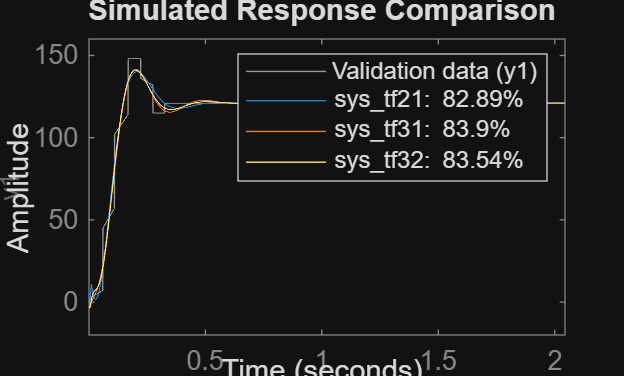


compare(data, sys_tf21, sys_tf31, sys_tf32);

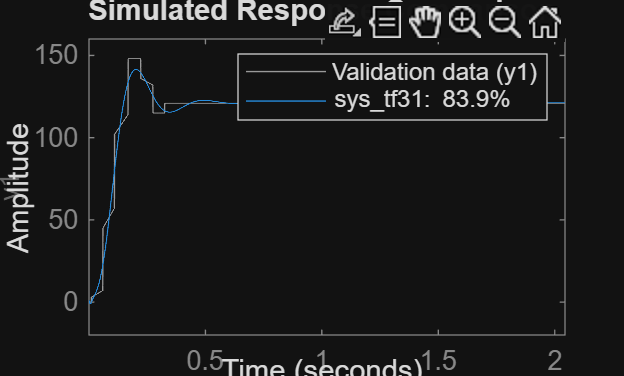

compare(data, sys_tf31);

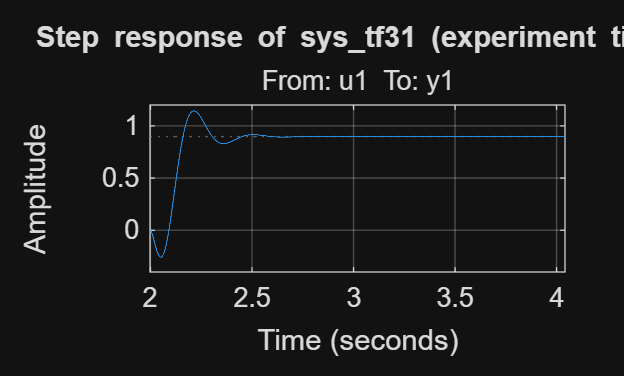

% plot final system sys_tf31
figure;
step(sys_tf31, t2);
grid on;
title('Step response of sys\_tf31 (experiment time)');